# Q3(a)

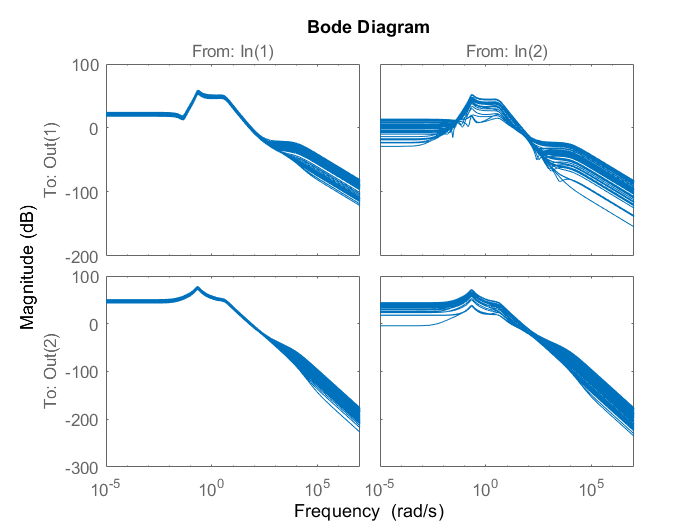

load responses.mat
A = [-0.0226 -36.6 -18.9 -32.1;0 -1.9 0.983 0;0.0123 -11.7 -2.63 0;0 0 1 0];
B = [0 0;-0.414 0;-77.8 22.4;0 0];
C = [0 57.3 0 0;0 0 0 57.3];
D = [0 0;0 0];
s = tf('s');
I = eye(4);
P0 = C*inv(s*I-A)*B+D;

bodemag(Gp_samples)

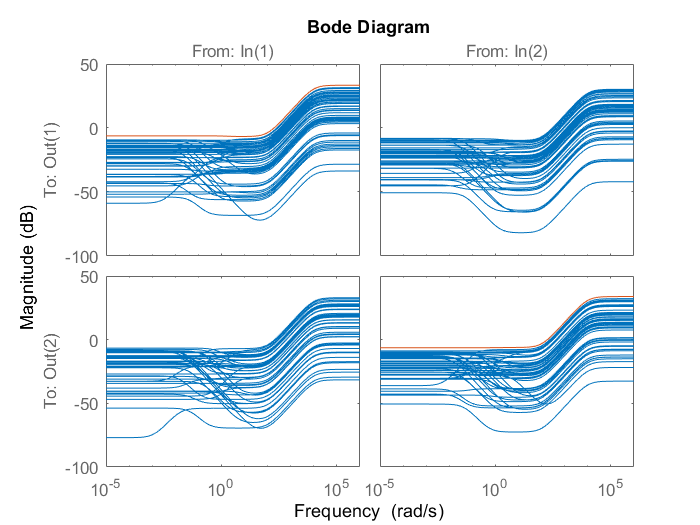

[P,info] = ucover(Gp_samples,P0,[4,4]);
bodemag(inv(P0)*Gp_samples-eye(2),info.W1)

# Q3(b)

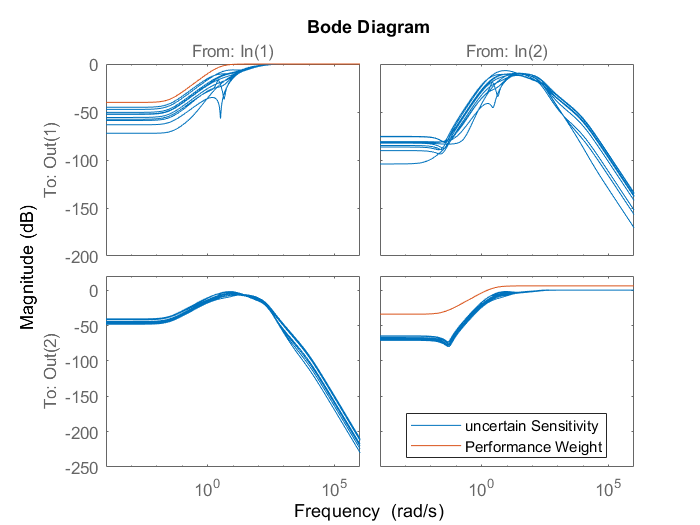

Wdel = info.W1;
Wp = [(s+3)/(s+0.03) 0;0 0.5*(s+3)/(s+0.03)];
Wn = [2*(s+1.28)/(s+320) 0;0 (s+1.28)/(s+320)];
PP = [zeros(2) zeros(2) zeros(2) Wdel; Wp*P0 zeros(2) Wp Wp*P0;P0 Wn eye(2) P0];
[K,CL,GAM] = hinfsyn(PP,2,2);
S = eye(2) - feedback(P*K,eye(2));
S = usample(S,10);
bodemag(S,inv(Wp))
legend('uncertain Sensitivity','Performance Weight','Location','best')

P_hat = [zeros(2) Wp Wp*P;Wn eye(2) P];

N = lft(P_hat,K);

isstable(N)

ans = logical
   1



[STABMARG,WCU] = robstab(N);
mu_s = 1/STABMARG.LowerBound

mu_s = 0.8909

[PERFMARG,WCU] = robustperf(N);
mu_p = 1/PERFMARG.LowerBound

mu_p = 2.3454

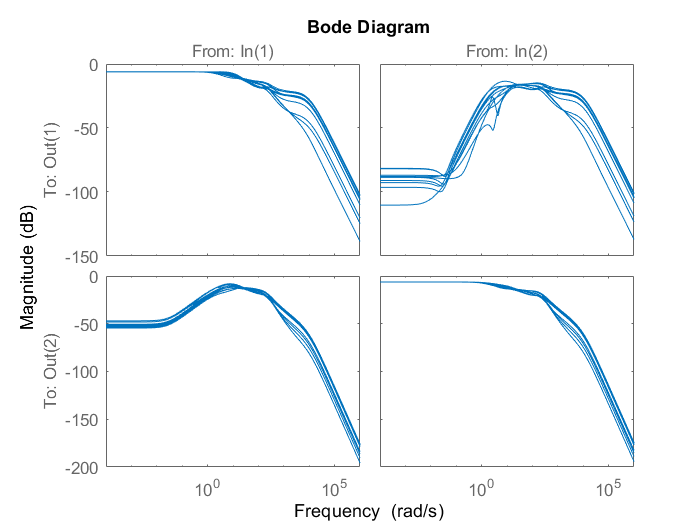


% Another Method for checking robust stability and robust performance
RS = Wdel*(eye(2)-S);
bodemag(RS)

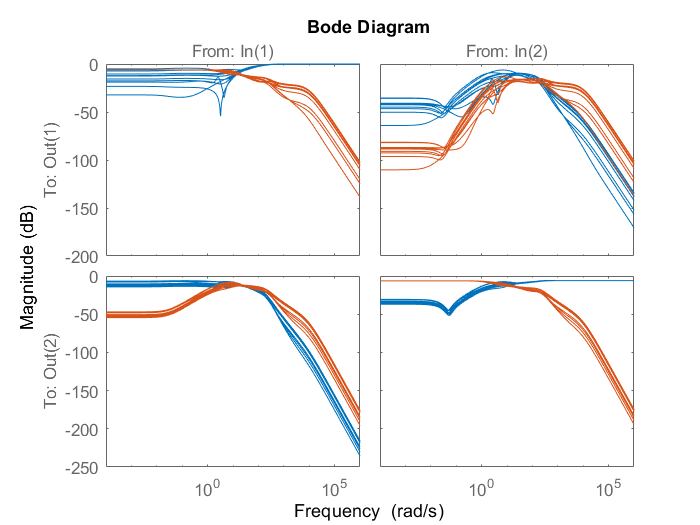

bodemag(Wp*S,Wdel*(eye(2)-S))

Here we can see that the bodemag of the sum of Wp*S and Wdel*T is crossing 0 dB, hence, having an infinity norm > 1. Hence, the system does not meet the robust performace criteria.